P1

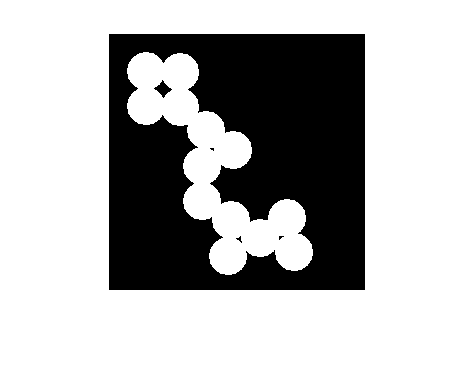

I = imread('circles.png');
imshow(I)

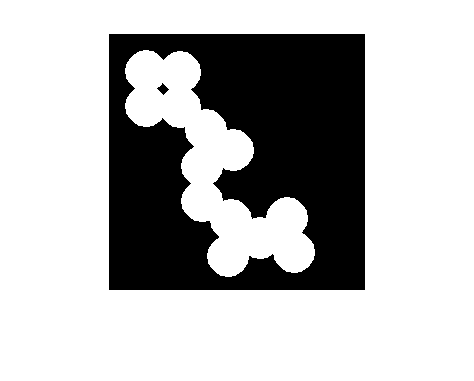

SE = strel("disk", 2);

imshow(imdilate(I, SE))

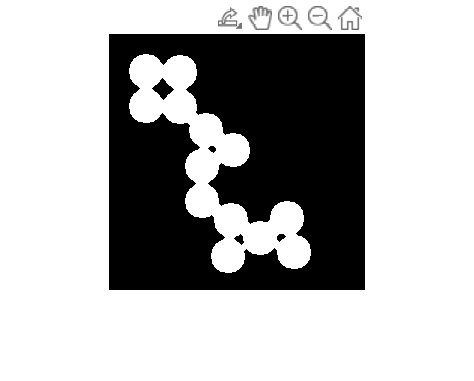

imshow(imerode(I,SE))

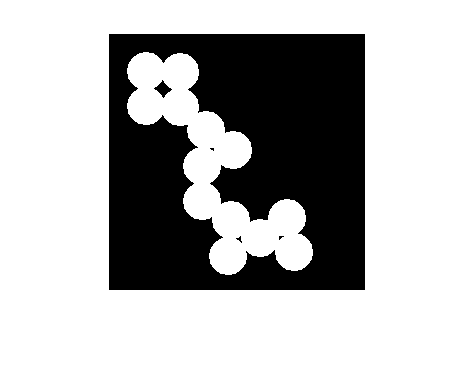


imshow(imopen(I,SE)) %erode then dilate

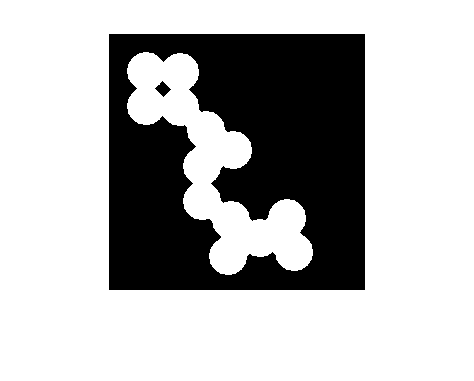

imshow(imclose(I,SE)) %dilate then erode

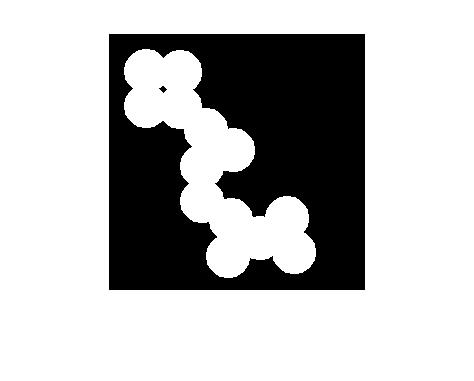


SE = strel("disk", 4);

imshow(imdilate(I, SE))

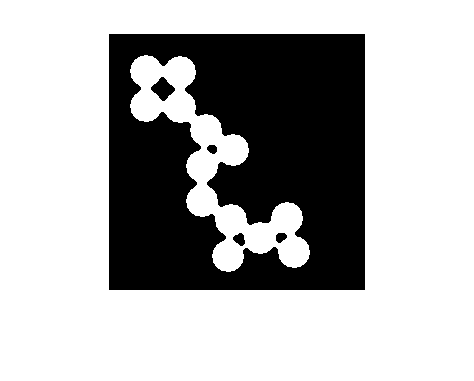

imshow(imerode(I,SE))


imshow(imopen(I,SE)) %erode then dilate

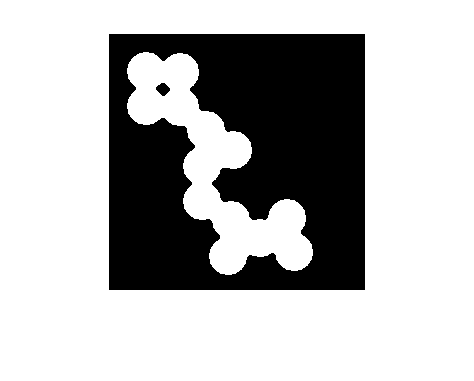

imshow(imclose(I,SE)) %dilate then erode

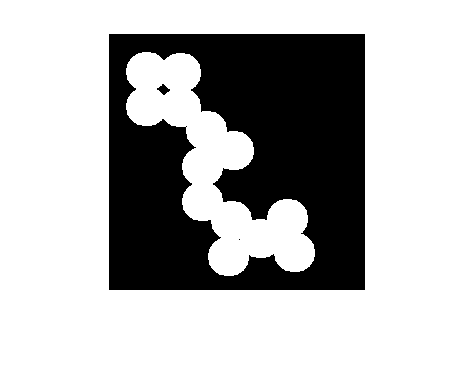


SE = strel("rectangle", [2 4]);

imshow(imdilate(I, SE))

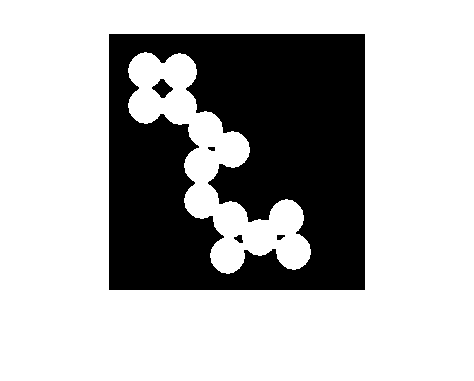

imshow(imerode(I,SE))


imshow(imopen(I,SE)) %erode then dilate

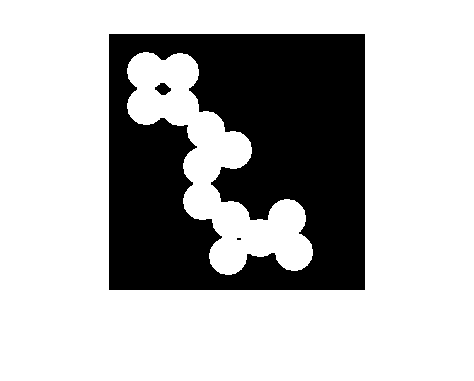

imshow(imclose(I,SE)) %dilate then erode

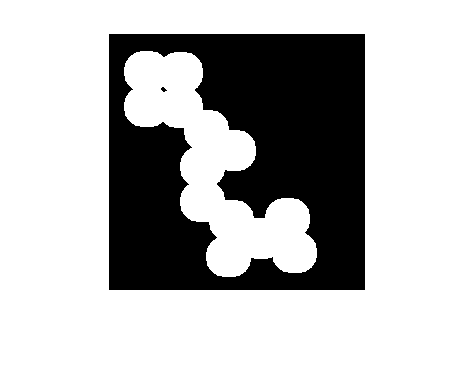


SE = strel("rectangle", [4,8]);

imshow(imdilate(I, SE))

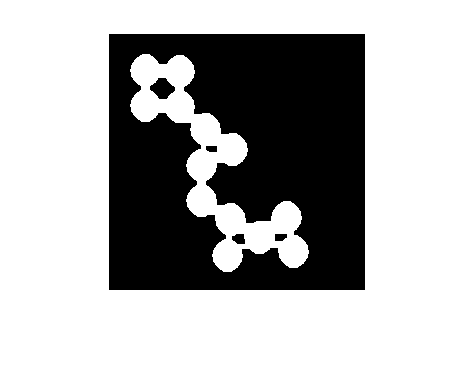

imshow(imerode(I,SE))

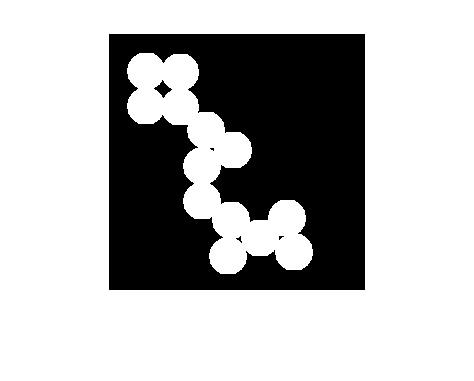


imshow(imopen(I,SE)) %erode then dilate

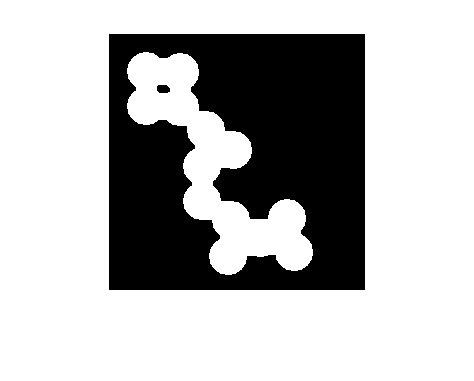

imshow(imclose(I,SE)) %dilate then erode

P2

cc = bwconncomp(I)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 1
    PixelIdxList: {[14134×1 double]}


mat = labelmatrix(cc)

mat = 256×256 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

regionprops(cc)

ans = struct with fields:
           Area: 14134
       Centroid: [106.6583 135.0756]
    BoundingBox: [18.5000 18.5000 186 223]


Extra Credit:

I_test = imresize(I, 0.1);
I_temp = I_test;
I_test = uint8(I_test); %assuming less than 256 labels
R = size(I_test, 1);
C = size(I_test, 2);
N = zeros(1,2);
label = 2;

for i = 1:R
    for j = 1:C
        if I_test(i,j) == 1
            N = getNeighbors(I_test, i,j);
            if (N(1) == 0) && (N(2) == 0)
                I_test(i,j) = label;
                label = label + 1; %new label if no neighbors
            elseif(((N(1) > 1) && (N(2) == 0)) || ((N(1) == 0) && (N(2) > 1))) %exactly one 1
                if(N(1) > 1)
                    I_test(i,j) = N(1); %assign left neighbor label 
                elseif(N(2) > 1)
                    I_test(i,j) = N(2); %assign right neighbor label
                else 
                    fprintf("Error"); %not supposed to go here
                end
            elseif((N(1) > 1) && (N(2) > 1))
                I_test(i,j) = min(N(1),N(2)); %if collision select min of labels
            end
        end
    end
end